%%%% Introduction to using MATLAB for connectome data

% Written by Stuart Oldham

## Example data

% Run the following command to load in some example data

load('example_connectome.mat')

% There are 4 variables; adj, connectome, COG and Labels. adj is an 82x82 
% group connectome generated from Human Connectome Project Data. connectome
% is a cell and each cell contains an individual subjects connectome. COG 
% are the MNI coordinates of each node and Labels is the name of each node 
% (i.e. what region each node is).

% Connectomes are a map of neural connections (axons, white matter tracts 
% etc)between regions (i.e. brain regions, cells etc). This can be
% expressed as an adjacency matrix (in this example the variable 'adj' is
% such a matrix). Each row i corresponds to a region as does every column
% j. The element (i,j) tells you if region i and j are connected. Regions
% are also called nodes/verticies and connections are also called edges

## Weighted and unweighted connectomes

% A connectome can either be unweighted or weighted. In an unweighted 
% connectome, the element i,j can either be 0 or 1. 0 indicates there is no
% connection between these regions while 1 indicates there is a connection.
% For weighted networks, each connection can be assigned a value > 0 
% indicating the strength (or weight) of a connection between two regions.

% The connectome here is currently weighted. Typically for dMRI data the
% weight of an edge corresponds to the number of streamlines connecting two
% regions. Here the number of steamlines connecting two regions has been
% corrected to account for variations in region size (i.e. larger regions 
% will have a disproportionate number of streamlines seeded from them)

% To make the connectome unweighted (or binarised) run the following:

bin = double(adj > 0);

% This finds all the elements that have a value > 0 (adj > 0) and creates a
% logical. A logical isa type of data which says if a condition is true or
% not. At every element > 0 the logical will assign a value of 1 and if not
% it will have a value of 0. The 'double' command converts the logical to a
% matrix

## Visualising connectomes

% Often it can be helpful to visualise the connectome in an image. This can
% help you get an idea of the network topology as well as see if anything
% has gone wrong. The command 'imagesc' is used for this purpose.

% It can also be helpful to change the colour map (i.e. what colours are
% used to represent which colours) as the MATLAB default isn't particularly
% great.

imagesc(log(adj))

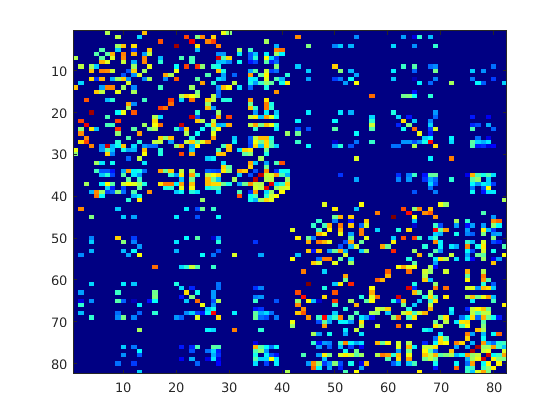

colormap('jet')


% We convert the values in the connectome to log values 'log(adj)' in order
% to make for easier visualisation. The colourmap scales according to the
% relative values in the matrix. As a handful of edges have significantly 
% higher weights than the rest of the network, most nodes will be coloured
% blue and be hard to distiguish from the background (i.e. no connections).
% What the log does is the distance between edge weights from absolute to
% relative values, essentially bringing all the values closer together.
% This allows for more of the colourmap to be sampled.

## Brain Connectivity Toolbox (BCT)

The Brain Connectivity Toolbox ([https://sites.google.com/site/bctnet/](https://sites.google.com/site/bctnet/)) contains many useful functions for analysing networks. Download from the website and unzip. Next you need to create a path pointing to this unziped folder using the command 'addpath'. For instance:

addpath(genpath('../2019_03_03_BCT'));

% Simply replace E:\Desktop\Honours_Data\BCT with the path for the BCT on
% your computer

## Node degree and strength

Degree refers to the total number of connections a node has to other nodes. Strength refers to the sum of the edge weights attached to a node. To find this values, it is easiest to use the Brain Connectivity Toolbox as they have inbuilt functions while will calculate these values. To calculate a nodes degree run

deg = degrees_und(adj);

% This will work no matter if the network is weighted or unweighted. The
% output 'deg' will be an array where deg(1) is the degree of node 1,
% deg(2) is the degree of node 2 etc.
%
% To calculate node strength run

str = strengths_und(adj);

% The network must be weighted for this to work. Again 'str' will be an
% array containing the strength of each node

## Degree distributions

The distribution of node degree and strength are important characteristics of a network. This distribution heavily influences many other parameters of a network

To find the degree/strength distributions, you simply need to create a histogram of the variables deg/str. For instance for the degree distribution do

hist(deg)

% A histogram should appear on your screen in a pop out box. Currently the
% histogram has 10 bins (i.e. columns). This can be changed by the
% following 'hist(data,x)' where x is the desired number of bins 

% Also is helpful to label the axis and give a title

title('Degree distribution')
xlabel('Node degree')
ylabel('Frequency')

## Strength distribution

% The same can be done to produce a strength distribution 

hist(str)
title('Strength distribution')
xlabel('Node strength')
ylabel('Frequency')

## Degree and strength distributions - subplots

% Subplots can also be useful to display multiple figures in the one
% window. The commands 'subplot(x,y,z)' is used for this purpose. x is the
% number of rows in the subplot, y is the number of columns and z is in
% which position you want to place a figure. So to have degree and strength
% distribution in the same image:

close all
subplot(1,2,1)
hist(deg)
title('Degree distribution')
xlabel('Node degree')
ylabel('Frequency')
subplot(1,2,2)
hist(str)
title('Strength distribution')
xlabel('Node strength')
ylabel('Frequency')

## BrainNetViewer - interface

% Download BrainNetViewer (https://www.nitrc.org/projects/bnv/) and unpack.
% Add this directory to the current path (again change the directory for
% where you have it

addpath(genpath('../BrainNet_Viewer'));

% Next you have to run a little function I wrote to get your data into a
% format BrainNetViewer recognises. It is in the format 
% BrainNetData(COG,Node_colour,Node_size,output_name,labels) where COG is
% the MNI coordinates of each node, Node_colour is how you want each node
% to be coloured (so each node with a Node_colour of 1 will be one colour,
% node with a value of 2 will be another colour etc), Node_size is how
% large you want each node to be, output_name is a string of what you want
% to name the output file and labels is the name of each node (optional).

% One issue with the current variable Labels is there is a space in the
% string (i.e. Left Accumbens, Right Superior Frontal etc). BrainNetViewer
% will freak out if it there are spaces so the spaces need to be replaced.

new_labels = cell(length(Labels),1);
for i = 1:length(Labels)
    new_labels{i,:} = strrep(Labels{i},' ','\_');
end

% Now the file can be generated

BrainNetData(COG,deg,str,'Degree',new_labels)

% This will output a file called 'Degree.node'. We can also create a .edge
% file containing all of the connections

dlmwrite('connections.edge', adj, '\t')

% BrainNetViewer can either be used in one of two ways. You can either
% interact with it using an interface or do everything through the command
% line.

% To use the GUI (Graphic User Interface) simply run

BrainNet

% Using File > Load File, select a surface, .node file and a .edge file. To
% select the surface file navigate to the BrainNetViewer folder and then go
% to Data/SurfTemplate and select a surface (BrainMesh_ICBM152.nv is what I
% use). I suggest copy what ever surface template you want to use into the
% folder that BrainNetViewer immediately opens up when you click 'Browse'
% to speed things up. Next navigate to your .node file and .edge file.
% Select 'Ok' and an options menu should appear. Most of the options are
% self explanatory (under the 'Edge' option in 'Draw Edge' I recommend not
% telling it to draw all edges, instead use the 'Above Threshold' slider.
% will have to experiment to see what give the best result, or just set it
% to the max and have no edges drawn).

## plotSurfaceRoiBoundary - an alternative visualisation function

% We need to tell MATLAB where the code to do the plotting is located.

addpath(genpath('../plotSurfaceROIBoundary'));

% This function will require some newer (higher-resolution data) which we
% can import. Note that this contains information for the left and right
% hemispheres separately ("lh_XXX" and "rh_XXX").

load('dataForPlotting_intro.mat');

% We can then start doing the plotting. plotSurfaceROIBoundary is the main
% function that does the plotting. It basically takes in a mesh describing
% the shape of the cortex, as well as how that mesh is supposed to be split
% up into different regions. You also have to tell it what value should be
% allocated to each region. It requires its inputs to be formatted and 
% ordered a certain way. First, we tell it the points (vertices) on the
% mesh, and how these points join together (faces). Then, we tell it which
% region each point is allocated to (lh_aparc). Then, we tell it what value
% to allocate to each region ( str(1:34) - as the left cortex has 34
% regions in it). The last three inputs format the output plot. 

close all; 
figure; 
plotSurfaceROIBoundary(...
    struct('faces', lh_faces, 'vertices', lh_verts), lh_aparc, ...
    str(1:34), 'faces', parula, 1);

% Finally, these few lines make the picture look a lot more pretty. 

camlight(80, -10); camlight(-80, -10); view([-90 0]);
axis off; axis tight; axis equal; 

% Try playing around with this figure! Note that you can zoom in and spin
% the figure around

## Creating functions

% It's nice to be able to plot a lateral view of the left hemisphere so
% prettily. But it's a lot to retype if we also want a medial view of that
% hemisphere - or perhaps views of the right hemisphere. What is the
% solution to this? We put all of those lines of code inside a function
% that we can call a lot more simply. That's exactly what's been done in
% brainplot_wrapper.m. This function has four inputs: the vertices, the
% faces, the region-allocations, and the data to plot. All the rest of the
% beautifying is done in the script. Make sure you have a look at that
% script.

close all;
figure('Position', [1 1 1000 1000]); 

subplot(2, 2, 1);
brainplot_wrapper(lh_verts, lh_faces, lh_aparc, str(1:34)); view([-90 0]);

subplot(2, 2, 2); 
brainplot_wrapper(lh_verts, lh_faces, lh_aparc, str(1:34)); view([90 0]);

subplot(2, 2, 3);
brainplot_wrapper(rh_verts, rh_faces, rh_aparc, str(42:75)); view([-90 0]);

subplot(2, 2, 4); 
brainplot_wrapper(rh_verts, rh_faces, rh_aparc, str(42:75)); view([90 0]);

% You might have noticed that similar lines of code are copied several
% times - one of the things we like to avoid when programming. As an
% exercise, you should try creating a new function of your own that
% simplifies even this process.

## Ploting degree/strength mean and variance across subjects - errorbars

% I believe you need this kind of information so I am going to propose a 
% way to do it but don't know if it is ideal or exactly what you want but 
% anyways.

% So I recommend you store each subjects connectome in a cell, in this
% case called connectome. All that is needed is a simple loop to get the
% degree and strength of each connectome

sub_deg = zeros(length(connectome),length(connectome{1})); 
sub_str = zeros(length(connectome),length(connectome{1}));
for i = 1:length(connectome)
    sub_deg(i,:) = degrees_und(connectome{i}); 
    sub_str(i,:) = strengths_und(connectome{i});
end

% I used the standard deviation to show variance but you can always replace
% this with the actual variance using the 'var' command (just replace any
% instance of std with var. I think standard deviation allows for slightly
% more intuitive understanding

mean_sub_deg = mean(sub_deg,2);
mean_sub_str = mean(sub_str,2);
std_sub_deg = std(sub_deg,0,2);
std_sub_str = std(sub_str,0,2);

% Before I make the figure, I am also going to
% label each subject by their "actual" ID (for illustrative purposes these
% subjects are just going to be named from 1:50). If you chose to do it
% this way just subsitite Sub_id with however you have labelled each
% subject (careful of underscores if you use them). Sub_id doesn't need to
% be a cell it can also be an array

Sub_id = cell(length(connectome));
for i = 1:length(connectome)
    Sub_id{i} = sprintf('Subject %d',i);
end

% Now to make the figure

close all

% Note this command 'figure('Position', [1 1 1400 600])' isn't required, it 
% just makes the figure a nice size automatically. Useful if you want to 
% save the figure automatically. You can change the numbers [1 1 1400 600]
% to change the size of the figure

figure('Position', [1 1 1400 600]);

subplot(2,1,1)
errorbar(mean_sub_deg,std_sub_deg,'rx');
xlim([0 length(connectome)+1]);
ax = gca;
ax.XTick = 1:length(connectome);
ax.XTickLabel = Sub_id;
ax.XTickLabelRotation = 90;
ylabel('Degree')
xlabel('Subject')
title('Degree variance across subjects');
subplot(2,1,2)
errorbar(mean_sub_str,std_sub_str,'bx');
xlim([0 length(connectome)+1]);
ax = gca;
ax.XTick = 1:length(connectome);
ax.XTickLabel = Sub_id;
ax.XTickLabelRotation = 90;
ylabel('Strength')
xlabel('Subject')
title('Strength variance across subjects');

## Ploting degree/strength mean and variance across subjects - boxplot

Another possible (and just ever so slightly easier) way is to use boxplots. Note the sub_deg and sub_str needs to be rotated (done by using ') so that each column is an individual subject. Unlike the chart done above plot the boxplot for degree and strength seperately (i.e. don't use subplots, figure will be too cramped)

close all

figure('Position', [1 1 1400 600]);
boxplot(sub_deg')
ax = gca;
ax.XTick = 1:length(connectome);
ax.XTickLabel = Sub_id;
ax.XTickLabelRotation = 90;
ylabel('Degree')
xlabel('Subject')
title('Degree variance across subjects');

figure('Position', [1 1 1400 600]);
boxplot(sub_str')
ax = gca;
ax.XTick = 1:length(connectome);
ax.XTickLabel = Sub_id;
ax.XTickLabelRotation = 90;
ylabel('Strength')
xlabel('Subject')
title('Strength variance across subjects');

## Ploting node degree/strength mean and variance across regions - errorbars

sub_deg = zeros(length(connectome),length(connectome{1})); 
sub_str = zeros(length(connectome),length(connectome{1}));
for i = 1:length(connectome)
    sub_deg(i,:) = degrees_und(connectome{i}); 
    sub_str(i,:) = strengths_und(connectome{i});
end

mean_sub_deg = mean(sub_deg,2);
mean_sub_str = mean(sub_str,2);
std_sub_deg = std(sub_deg,0,2);
std_sub_str = std(sub_str,0,2);

close all

figure('Position', [1 1 1400 600]);
errorbar(mean_sub_deg,std_sub_deg,'rx');
xlim([0 length(connectome)+1]);
ax = gca;
ax.XTick = 1:length(connectome{1});
ax.XTickLabel = Labels;
ax.XTickLabelRotation = 90;
ylabel('Degree')
xlabel('Node/Region')
title('Node degree variance across subjects');

figure('Position', [1 1 1400 600]);
errorbar(mean_sub_str,std_sub_str,'bx');
xlim([0 length(connectome)+1]);
ax = gca;
ax.XTick = 1:length(connectome);
ax.XTickLabel = Labels;
ax.XTickLabelRotation = 90;
ylabel('Strength')
xlabel('Node/Region')
title('Node strength variance across subjects');

## Ploting node degree/strength mean and variance across regions - boxplot

close all

figure('Position', [1 1 1400 600]);
boxplot(sub_deg)
ax = gca;
ax.XTick = 1:length(connectome{1});
ax.XTickLabel = Labels;
ax.XTickLabelRotation = 90;
ylabel('Degree')
xlabel('Node/Region')
title('Node degree variance across subjects');

figure('Position', [1 1 1400 600]);
boxplot(sub_str)
ax = gca;
ax.XTick = 1:length(connectome{1});
ax.XTickLabel = Labels;
ax.XTickLabelRotation = 90;
ylabel('Strength')
xlabel('Node/Region')
title('Node strength variance across subjects');